# Sessió 10

**Yaiza Cano, Narcís Terrado **

Per tal d'utilitzar la app de *Classification Learner* que ens proporciona matlab per classificar espècies de fulles a partir de les seves imatges hem de preparar les dades. Utilitzem els descriptors de fourier com a vector de caracteristiques. Hem posat tota la lògica per a l'extracció dels descriptors de Fourier a la funció *getFourier* per tal de mantenir el codi net. L'objectiu de la funció és obtenir els descriptors de fourier a partir de la imatge i posar-los a una fila que desprès usarem per posar a la taula pel *Classification Learner. *

La taula que user pel *Classification Learner* té tantes columnes com descriptors de Fourier més una columna per identificar l'espècie, i tantes files com imatges.

El que fem és: per a cada directori que conté les imatges, apliquem la funcio *getFourier *a les imatges, i guardem els descriptors a una fila de la taula juntament amb l'espècie de la fulla que estem tractant.

D'aquesta manera obtenim una taula amb 301 columnes (300 descriptors + l'espècie) i 48 files (tantes com imatges)

El *Classification Learner *detecta els 300 descriptors com a *features* i la columna d'espècie com a *response*. 

fourier = [];
species = [];
ndesc = 300;
fulles = dir;
sp2 = cell(1,1);
for j = 3:length(fulles)
    s = fulles(j).name;
    cd (s)
    d = dir;
    [rows, ~] = size(d);
    for i = 3:rows
        im = imread(d(i).name);
        f = getFourier(im,ndesc);
        fourier = [fourier;f];
        species = [species;cellstr(s)];
    end
    cd ..
end
t = table(fourier,species);

## Experiments realitzats:

Una vegada al Classification Learner hem provat d'executar tots els models per veure quin donava millors resultats. Al principi hem usat tots els predictors, els 300 descriptors de Fourier.  Amb els 300 descriptors, el model que donava millors resultats era el Linear Discriminant, amb una precisió de 95,8%. A partir d'aquest model hem estat fent proves per determinar quins eren els predictors (en el nostre cas descriptors de Fourier) més significatius per a obtenir millors resultats, 97,9% de precisió. Utilitzant el Parallel Coordinates Plot i el Scatter Plot hem anat provant amb diferents descriptors. 

En el cas del Scatter Plot miravem quins eren els parells de descriptors que més separaven les dades. Després d'unes proves, determinem que el descriptor 44 i el 21 categoritzen les dades prou bé.  

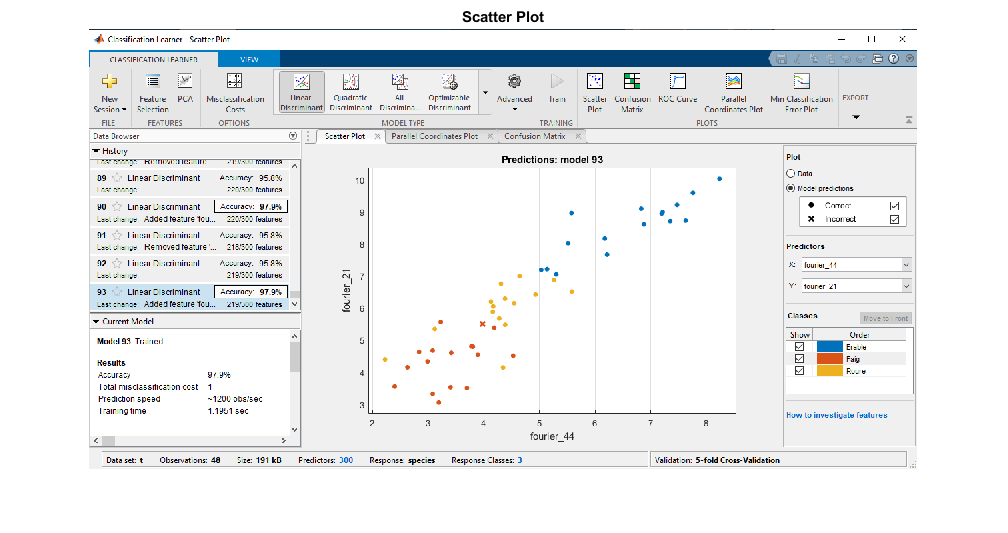

scatter = imread('ScatterPlot.png');
figure, imshow(scatter); title('Scatter Plot')

Amb el Parallel Coordinates Plot hem estat provant amb diferents descriptors intentant determinar quins eren els descriptors més significatius. Gràcies a aquest plot podem visualitzar quins són els descriptors que tenen les tres categories menys separades, i podem entrenar el model de nou sense aquell predictor. Hem anat determinant quins predictors són menys significatius i provant d'entrenar de nou el model, quedant-nos amb una precisió igual i fins i tot en algun cas augmentant-la.

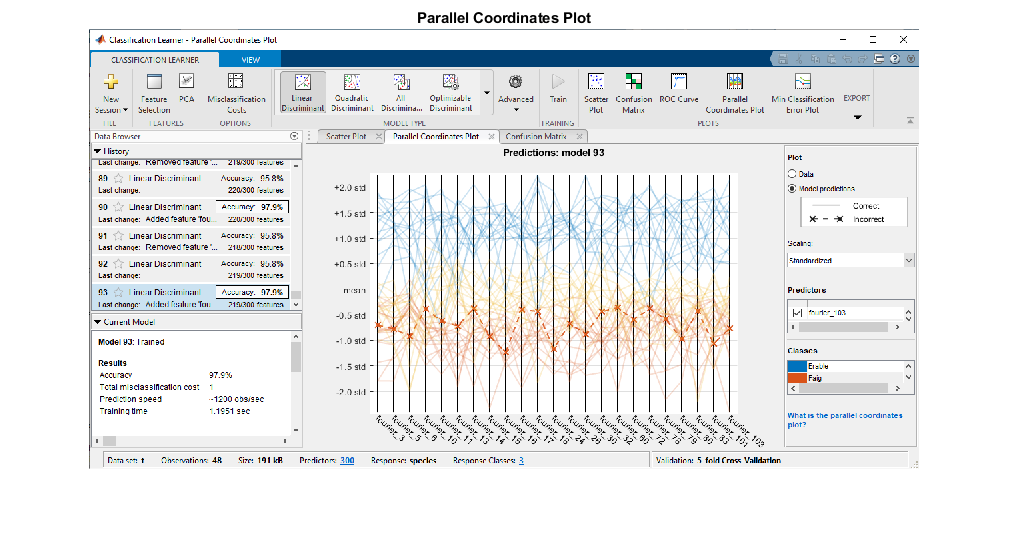

parallel = imread('ParallelCoordsPlot.png');
figure, imshow(parallel);title('Parallel Coordinates Plot')

Finalment, hem fet una última ullada a la Confusion Matrix per distinguir, d'una manera més agradable visualment, la precisió del nostre model.

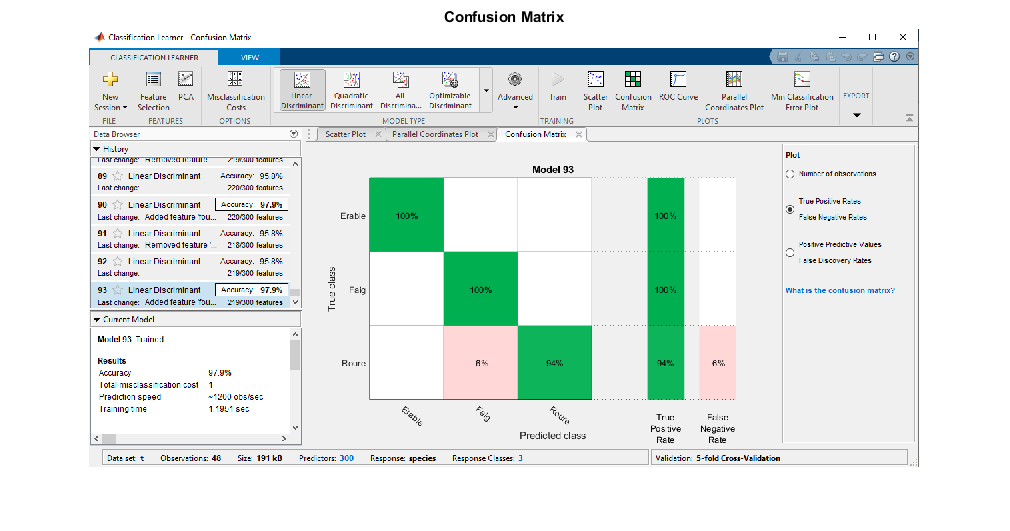

confusion = imread('ConfusionMatrix.png');
figure, imshow(confusion); title('Confusion Matrix');

Tot i que ja hem explicat que el Linear Discriminant és el plot que millor resultats ens donava, hem volgut exportar el Coarse Tree per veure l'arbre de classificació del model.

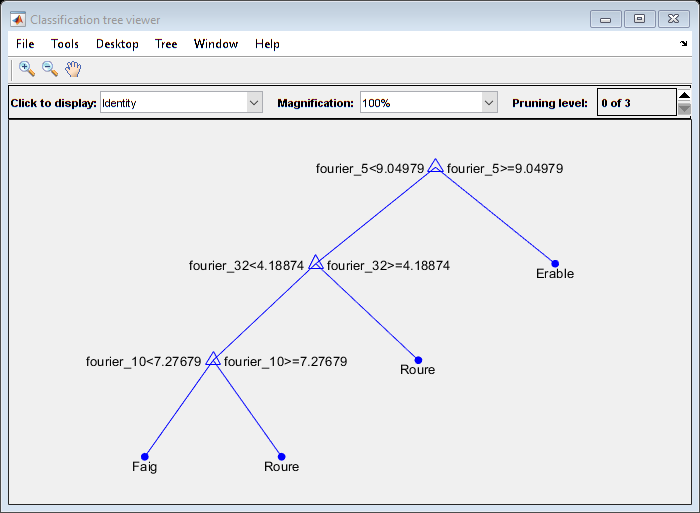

view(trainedCoarseModel.ClassificationTree,'mode','graph');

type getFourier.m


function [fourier] = getFourier(im, ndesc)
im = imresize(im,1/4);
im = rgb2gray(im);
br = imbinarize(im);
br = imcomplement(br);


%obtenim el contorn
ero = imerode(br, strel('disk',1));
cont = xor(ero,br);

%obtenim les coordenades del contorn
[fila, col] = find(br, 1); %busquem el primer pÃ­xel
B = bwtraceboundary(br, [fila, col], 'E'); %direcciÃ³ est a l'atzar
%B contÃ© les coordenades


%centrem coordenades
mig = mean(B);
B(:,1) = B(:,1) - mig(1);
B(:,2) = B(:,2) - mig(2);

%convertim les coordenades a complexes
s = B(:,1) + 1i*B(:,2);

%cal que la dimensiÃ³ del vector sigui parell
[mida, ~]=size(B);
if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
end
%calculem la Fast Fourier Transform
z = fft(s);

tmp = z;
tmp(ndesc+1:end-ndesc) = 0; %eliminem els del mig perquÃ¨ es duplica l'espectre
% ho displaiem logaritmic perquÃ¨ sinÃ³ no es veu res
logz = log(abs(tmp));

fourier = logz(1:ndesc,:);
fourier = fourier.';
end

